## Extract App Graphs using Map Reduce

An optimized version of muBench Alibaba Example Script, utilizing parallelism to handle larger input data

[https://de.mathworks.com/help/matlab/ref/mapreduce.html](https://de.mathworks.com/help/matlab/ref/mapreduce.html)

### Parallelism

Parts of this script profit from parallel execution (requires Parallel Computing Toolbox)

**Run only one of two sections below...**

### Enabling parallel computing

Run this scetion to (re-)enable parallel mapreducing

Note: The debugger will not work within map-reduce parts while this is ON

mapreducer(gcp);

Starting parallel pool (parpool) using the 'Processes' profile ...
Parallel pool using the 'Processes' profile is shutting down.



### Disabling parallel computing

Run this scetion to disable parallel mapreducing

Note: This will allow the debugging of map-reduce parts.

mapreducer(0);

## Actual Script below

### Prepare selected columns

We may not care about certain columns, once we fully understand the trace data.

[trace_header, trace_formats, trace_vartypes] = constants();
ignore_columns = ["response_time"];
used_col_idx = ~ismember(trace_header, ignore_columns);
trace_selected_cols = trace_header(used_col_idx);
trace_selected_vartypes = trace_vartypes(used_col_idx);
trace_selected_formats = trace_formats(used_col_idx);

clear trace_formats;
clear trace_vartypes;

### Create Datastore

Read in .csv and create a datastore that can be used with mapreduce.

[trace_location, trace_header_lines, ~, ~, ~, ~, ~] = config();
ds = tabularTextDatastore(trace_location, "NumHeaderLines", trace_header_lines, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...
    "MissingValue", 0, ...
    "VariableNames", trace_header, ...
    "SelectedFormats", trace_selected_formats, ...
    "SelectedVariableNames", trace_selected_cols);
preview(ds)

clear trace_location;
clear trace_header_lines;

### Map Reduce to find valid trace ids

This section filters out invalid traces

Invalidation Criteria:

- interface, upstream_ms or downstream_ms is "UNKNOWN" or "UNAVAILABLE"

- The rpc_id parent of an entry of one trace_id is not present

- An entry of one trace_id is not connected to the "USER" upstream entry

col_idx_trace_id = strcmp(trace_header, "trace_id") > 0;
% wrap mapper function to pass variable context
mapFunc = @(a, b, c)trace_mapper(a, b, c, col_idx_trace_id);
% wrap reducer function to pass empty table obj
empty_table = table('Size', [0 length(trace_selected_vartypes)], 'VariableTypes',trace_selected_vartypes, 'VariableNames',trace_selected_cols);
reduceFunc = @(a, b, c)trace_reducer(a, b, c, empty_table);
tic
trace_ds = mapreduce(ds, mapFunc, reduceFunc, 'OutputFolder', './results');
toc
clear empty_table;
clear col_idx_trace_id;
clear mapFunc;
clear reduceFunc;

### Data Example

Optional: Gives a preview of the data.

prev_trace_ds = copy(trace_ds);
reset(prev_trace_ds);
trace_prev_ds.ReadSize = 10;
prev_trace_data = read(prev_trace_ds);
prev_trace_data.Value{:,1}

### Map Reduce to services

This section filters out invalid traces and stores the resulting trace entries grouped by service

col_idx_service = strcmp(trace_header, "service") > 0;
% wrap mapper function to pass variable context
mapFunc = @(a, b, c)service_mapper(a, b, c, col_idx_service);
% wrap reducer function to pass empty table obj
empty_table = table('Size', [0 length(trace_selected_vartypes)], 'VariableTypes',trace_selected_vartypes, 'VariableNames',trace_selected_cols);
reduceFunc = @(a, b, c)service_reducer(a, b, c, empty_table);
tic
service_ds = mapreduce(trace_ds, mapFunc, reduceFunc, 'OutputFolder', './results');
toc
clear empty_table;
clear col_idx_service;
clear mapFunc;
clear reduceFunc;

### Data Example

Optional: Gives a preview of the data.

prev_svc_ds = copy(service_ds);
reset(prev_svc_ds);
prev_svc_ds.ReadSize = 10;
prev_svc_data = read(prev_svc_ds);
prev_svc_data.Value{:,1}

### Service Graphs

Create directed graphs from the trace entries related to a specific service.

tic
service_graph_ds = mapreduce(service_ds, @service_graph_mapper, @service_graph_reducer, 'OutputFolder', './results');
toc

### Port dataformat

From MapReduce KeyValueDatastore output to serial processing

(we leave the map-reduce environment and process classically)

service_graphs = readall(service_graph_ds);

### Prepare Input

Prepare input data to be a nicely accessible table

% Flatten service_graphs.Value into a table with 3 columns
value_as_table = cell2table(service_graphs.Value);
flattened_values = cell2table(value_as_table{:,1});
services = [service_graphs.Key flattened_values];
% Label Columns
services.Properties.VariableNames(1) = "service_id";
services.Properties.VariableNames(2) = "graph";
services.Properties.VariableNames(3) = "possible_node_names";
services.Properties.VariableNames(4) = "ms_count";
services.Properties.VariableNames(5) = "max_depth";
services.Properties.VariableNames(6) = "trace_count";


clear value_as_table;
clear flattened_values;

clear service_graphs;

heatmap(services,"max_depth","ms_count","ColorScaling","log");

### Filter Input

About 31500 of the ~36000 services only have a ms_count of 1 (monoliths).

TODO: Would be interesting to see, how many of these are mem-cached (results).

To reduce the computing time for clustering and provide proper scales we split up the input data.

monolith_idx = services.ms_count < 2;
monoliths = services(monolith_idx,:);
microservices = services(~monolith_idx,:);

heatmap(microservices,"max_depth","ms_count","ColorScaling","log");

byMSCount = groupsummary(service_clusters,"ms_count")
bar(byMSCount.ms_count, byMSCount.GroupCount);
title("Services by involved service count");
yscale log;
ylabel("Service Count");
xlabel("# of involved services");

### Create X clusters

We inspect the found service graphs for similarity and cluster them into N+1 parts.

We will treat all monoliths as one cluster and the microservices share the other N clusters.

### Calculate service similarities

tic
microservice_similarity_matrix = service_similarity(microservices);
toc

### Calculated results for ideal cluster count in relation to similarity threshold

Can be skipped, keeps track of optimal cluster numbers depending on similarity_thresholds

similarity_thresholds = [0.6; 0.7; 0.8];
ideal_clusters = [70; 32; 15];
table(similarity_thresholds, ideal_clusters)
clear similarity_thresholds;
clear ideal_clusters;

### Binary similarity matrix

[~, ~, ~, ~, ~, similarity_threshold, ~] = config();
logical = microservice_similarity_matrix > similarity_threshold;
binary_similarity_matrix = single(logical);
clear logical;
clear similarity_threshold;

### Find optimal cluster number

For pure reproduction this step could be skipped.

myfunc=@(X,K)(spectralcluster(X,K));
tic

ans = 3×2 table
    similarity_thresholds    ideal_clusters
    _____________________    ______________

             0.6                   70      
             0.7                   32      
             0.8                   15      


k_opt=evalclusters(binary_similarity_matrix,myfunc,'CalinskiHarabasz','klist',69:75);
toc
ms_cluster_count = k_opt.OptimalK
clear myfunc;
clear k_opt;

#### Cluster microservices

% un-comment to override cluster count
ms_cluster_count = 15;
limit = height(microservices);

Clustering into 15 clusters

% limit = 1000;

Elapsed time is 163.205029 seconds.


tic
[microservice_clusters] = service_clustering(microservices(1:limit,:),binary_similarity_matrix,ms_cluster_count);
toc
clear limit;

#### Prepare and monolith data

% Create output table
monolith_cluster_nr = ones(height(monoliths),1) + ms_cluster_count;
monolith_clusters = [monoliths table(monolith_cluster_nr)];
% Label Columns
monolith_clusters.Properties.VariableNames(width(monolith_clusters)) = "cluster";

clear monolith_cluster_nr;

### Combine microservices and monolith clusters

% TODO: remove speed-workaround
monolith_clusters = [];
service_clusters = [microservice_clusters; monolith_clusters];

clear microservice_clusters;
clear monolith_clusters;

### Inspect depth and ms count by cluster

meansByCluster = groupsummary(service_clusters,"cluster","mean",["max_depth","ms_count"])
bar(meansByCluster.cluster, meansByCluster.GroupCount)
title("Count by Group");
yscale log;
ylabel("Service Count");
xlabel("Cluster #");

### Sample services

Extract a sample of % services, as we do not want to deploy 38k services.

Workload with muBench is mainly generated through requests, so we do not only have a choice of "which services", but also "how many requests for the selected services"

[~, ~, ~, ~, ~, ~, sampling_factor] = config();
fprintf("Sampling factor: %d", sampling_factor);

Sampling factor: 1.000000e-02

[service_samples] = service_sampling(service_clusters, sampling_factor)

service_samples = 56×7 table
      service_id       possible_node_names    ms_count    trace_count    cluster    service_cluster_share    trace_factor
    _______________    ___________________    ________    ___________    _______    _____________________    ____________

    {'S_86516878' }        {4×1 cell}            10          58997          1               0.99325            0.056872  
    {'S_137399339'}        {1×1 cell}             5            176          1             0.0029631            0.056872  
    {'S_115862686'}        {2×1 cell}             5             61          1              0.001027            0.056872  
    {'S_124838279'}        {2×1 cell}             5             47          1            0.00079127            0.056872  


clear sampling_factor;

### Manual Sanity Checks on sampled data

% select all MS graphs
plot_selection = service_samples(service_samples.cluster <= ms_cluster_count,:)

plot_selection = 56×7 table
      service_id       possible_node_names    ms_count    trace_count    cluster    service_cluster_share    trace_factor
    _______________    ___________________    ________    ___________    _______    _____________________    ____________

    {'S_86516878' }        {4×1 cell}            10          58997          1               0.99325            0.056872  
    {'S_137399339'}        {1×1 cell}             5            176          1             0.0029631            0.056872  
    {'S_115862686'}        {2×1 cell}             5             61          1              0.001027            0.056872  
    {'S_124838279'}        {2×1 cell}             5             47          1            0.00079127            0.056872  
 

Plot graph samples

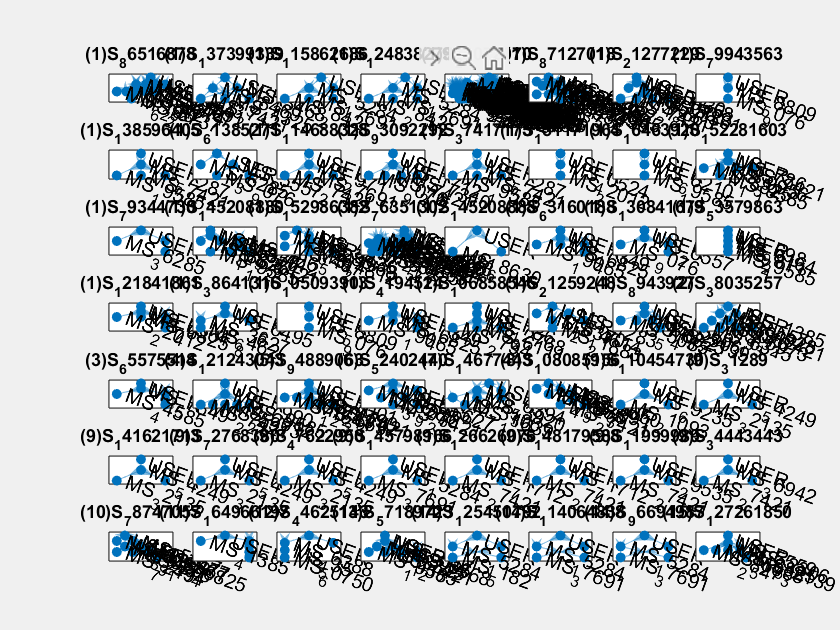

% plot_selection = microservices(ismember(microservices.service_id, service_samples.service_id),:);
plot_count = height(plot_selection);
% plot_count = 9;
subplot_cols = ceil(sqrt(plot_count));
subplot_rows = ceil(plot_count / subplot_cols);
f = figure();
set(f,'Visible','off');
for i=1:plot_count
    cluster = plot_selection.cluster(i);
    g = microservices.graph(strcmp(microservices.service_id, service_samples.service_id(i)), :);
    t = "(" + cluster + ")" + plot_selection.service_id{i};
    subplot(subplot_rows,subplot_cols,i);
    plot(g{1});
    title(t);
end
set(f,'Visible','on');

### App Graphs

Construct graphs for each app (cluster)

% needs adaptation
% [apps] = cluster_graphs(service_clusters);